clear
clc

% Параметры
Theta_total = 2720; % полный угол [град]
T_total = 4;        % общее время [с]
T_acc = 2;          % время разгона [с]
T_dec = 2;          % время торможения [с]
T_const = T_total - T_acc - T_dec; % участок с постоянной скоростью

% Макс ускорение через интеграл синусоида:
% Разгон по синусу:
% omega_max = 2*A_max*T_acc/pi
% путь на разгоне = A_max*T_acc^2/pi

A_max = Theta_total * pi / (4*T_acc^2 + 2*T_acc*T_const);
% Общий путь:
% Theta_total = 2*(A_max*T_acc^2/pi) + omega_max * T_const

% Выражаем A_max:
omega_max = 2*T_acc/pi; % относительный коэффициент
S_acc = (2/pi) * A_max * T_acc^2; % угол на разгон/торможение
S_const = omega_max * A_max * T_const;

% Уравнение баланса угла:
% Theta_total = 2*S_acc + S_const
% подставляем:
% Theta_total = 2*(A_max*T_acc^2/pi) + (2*A_max*T_acc/pi)*T_const

A_max = Theta_total / ( 2*(T_acc^2/pi) + 2*T_acc*T_const/pi );

% Время и инициализация
dt = 0.01;
t = 0:dt:T_total;
theta = zeros(size(t));
omega = zeros(size(t));
alpha = zeros(size(t));

for i = 2:length(t)
    ti = t(i);

    if ti <= T_acc
        % Разгон: ускорение по синусу
        alpha(i) = A_max * sin( pi * ti / T_acc );
    elseif ti <= T_acc + T_const
        % Постоянная скорость
        alpha(i) = 0;
    elseif ti <= T_acc + T_const + T_dec
        % Торможение: зеркально
        tau = ti - (T_acc + T_const);
        alpha(i) = -A_max * sin( pi * tau / T_dec );
    else
        alpha(i) = 0;
    end

    omega(i) = omega(i-1) + alpha(i) * dt;
    theta(i) = theta(i-1) + omega(i) * dt;
end


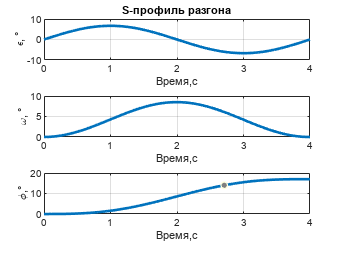

% Графики
figure;
subplot(3,1,3); plot(t, theta/160, 'LineWidth',2); grid on; ylabel('\phi,°'); xlabel('Время,с');
subplot(3,1,2); plot(t, omega/160,'LineWidth',2); grid on; ylabel('\omega, °');xlabel('Время,с');
subplot(3,1,1); plot(t, alpha/160,'LineWidth',2); grid on; ylabel('\epsilon, °');title("S-профиль разгона");xlabel('Время,с');
saveas(gcf, 'S-curve.png');        % PNG

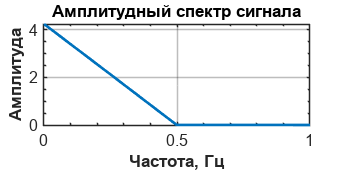

% Преобразование Фурье
Fs = 1/dt;
N = length(t);
f = (0:N-1)*(Fs/N);

fftAll = fft(omega/160);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2)); % <-- правильно
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 1]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');

saveas(gcf, 'S-curve-fourier.png');        % PNG

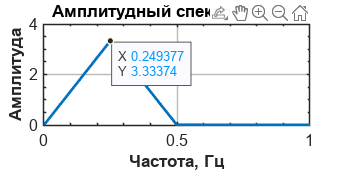

% Преобразование Фурье
Fs = 1/dt;
N = length(t);
f = (0:N-1)*(Fs/N);

fftAll = fft(alpha/160);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2)); % <-- правильно
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 1]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');

saveas(gcf, 'S-curve-fourier.png');        % PNG